clear
subject = "92a04"; ses = "post";
fileName ="iTBS_"+subject+"_"+ses+".mat";
cd("C:\Users\Katherine\Documents\AAA UW\Herron Lab\Data\" + subject)
load(fileName)

stimpairs = [anode cathode];
N_trials = length(stimpairs);
N_chan = size(data_artrem,2);
N_pair = length(unique(stimpairs,'rows'))/2;

onsets_bychan = cell(1,N_chan); % stim onsets for each channel
onsets_bypair = cell(1,N_pair); % stim onsets for each stim pair
for i=1:N_chan
    onsets_bychan{i} = onsets_samps(anode==i | cathode==i);
end
if N_pair > 7
    for i=1:7
        onsets_bypair{i} = onsets_samps((anode==i & cathode==i+1) | (anode==i+1 & cathode==i));
    end
    for i=9:N_chan-1
        onsets_bypair{i-1} = onsets_samps((anode==i & cathode==i+1) | (anode==i+1 & cathode==i));
    end
else
    for i=1:N_pair
        onsets_bypair{i} = onsets_samps((anode==i & cathode==i+1) | (anode==i+1 & cathode==i));
    end
end

data_artsmooth = data_artrem;
for C_s=1:N_chan
    for i=1:length(onsets_bychan{C_s})
        stim_onset = onsets_bychan{C_s}(i);
        if stim_onset==onsets_samps(end)
            break
        else
            next_stim = onsets_samps(find(onsets_samps == stim_onset) + 1);
            replace_window = data_artrem(stim_onset:next_stim-ceil(.1*fs),C_s);
            new_values = linspace(replace_window(1),replace_window(end),length(replace_window));
            data_artsmooth(stim_onset:next_stim-ceil(.1*fs),C_s) = new_values;
        end
    end
end

order = 3;
freqs = {.5 200 [53,63] [117,123] [177,183]};
ftype = ["high" "low" "stop" "stop" "stop"];
data_filt2 = double(data_artsmooth);
for i=1:length(freqs)
    freq = freqs{i};
    [b,a] = butter(order,freq/(fs/2),ftype(i));
%     freqz(b, a, 0:.1:400, fs);
    data_filt2 = filtfilt(b,a,data_filt2);
end

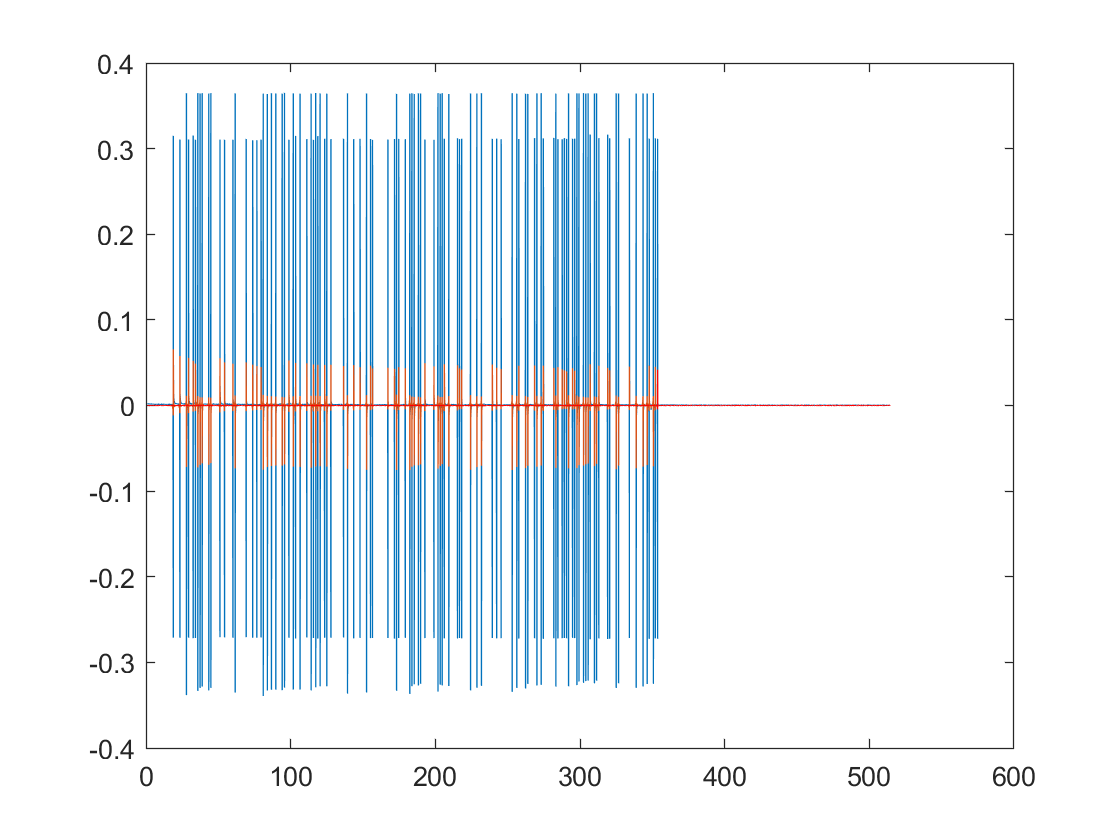

figure()
C_r = 12;
x = linspace(1,length(data_artrem)/fs,length(data_artrem)); % units of time
plot(x,data_artrem(:,C_r))
hold on
plot(x,data_filt(:,C_r))
plot(x,data_filt2(:,C_r),'r')

save(fileName,'data_artsmooth','data_filt2','-append')